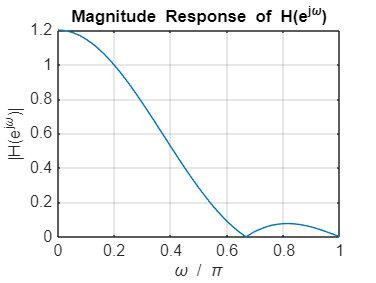

h = [0.2 0.4 0.4 0.2];
[H, w] = freqz(h, 1, 512);

plot(w/pi, abs(H));
title('Magnitude Response of H(e^{j\omega})');
xlabel('\omega / \pi'); ylabel('|H(e^{j\omega})|'); 
grid on;

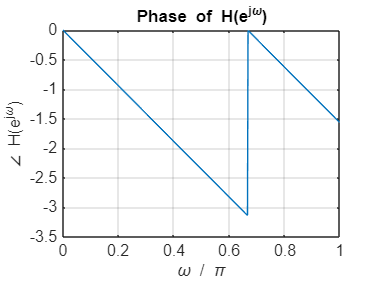



plot(w/pi, angle(H));
title('Phase of H(e^{j\omega})');
xlabel('\omega / \pi');
ylabel('\angle H(e^{j\omega})');
grid on;

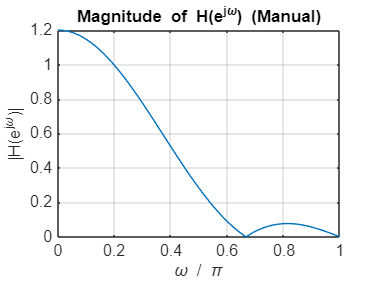


H_manual = 0.2 + 0.4*exp(-1j*w) + 0.4*exp(-1j*2*w) + 0.2*exp(-1j*3*w);
[H, w] = freqz(h, 1, 512);

figure;

plot(w/pi, abs(H_manual));
title('Magnitude of H(e^{j\omega}) (Manual)');
xlabel('\omega / \pi');
ylabel('|H(e^{j\omega})|');
grid on;

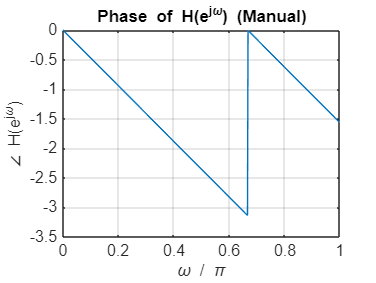


plot(w/pi, angle(H_manual));
title('Phase of H(e^{j\omega}) (Manual)');
xlabel('\omega / \pi');
ylabel('\angle H(e^{j\omega})');
grid on;


H_mag = abs(H);
peak = max(H_mag);
cutoff_mag = 0.707 * peak;
index = find(H_mag <= cutoff_mag, 1, 'first');
cutoff_w = w(index);

fs1 = 4000;
fc1 = cutoff_w * fs1 / (2*pi);
fprintf('Cutoff Frequency1: %.4f*pi (%.2f Hz)\n', cutoff_w/pi, fc1);

Cutoff Frequency1: 0.2695*pi (539.06 Hz)



fs2 = 8000;
fc2 = cutoff_w * fs2 /(2*pi);
fprintf('Cutoff Frequency2: %.4f*pi (%.2f Hz)\n', cutoff_w/pi, fc2);

Cutoff Frequency2: 0.2695*pi (1078.12 Hz)
